# Build Map from 2-D Lidar Scans Using SLAM

This example shows you how to implement the simultaneous localization and mapping (SLAM) algorithm on a series of 2-D lidar scans using scan processing algorithms and pose graph optimization (PGO). The goal of this example is to estimate the trajectory of the robot and build a map of the environment.

The SLAM algorithm in this example incrementally processes the lidar scans and builds a pose graph to create the map of the environment. To overcome the drift accumulated in estimated robot trajectory, the example recognizes previously visited places through scan matching and utilizes the loop closure information to optimize poses and update the map of the environment. To optimize the pose graph, this example uses 2-D pose graph optimization from Navigation Toolbox™.

In this example, you learn how to:

- Estimate robot trajectory from a series of scans using scan registration algorithms.

- Optimize the drift in estimated robot trajectory by identifying previously visited places (loop closures).

- Visualize the map of the environment using scans and their absolute poses.

## Load Laser Scans

This example uses data collected in an indoor environment using a Jackal™ robot from Clearpath Robotics™. The robot is equipped with a SICK™ TiM-511 laser scanner with a maximum range of 10 meters. Load the `offlineSlamData.mat` file containing the laser scans into the workspace.

load('data8.mat');


scans{1}

ans =   lidarScan - 속성 있음:

       Ranges: [584×1 double]
       Angles: [584×1 double]
    Cartesian: [584×2 double]
        Count: 584


%data = load('garage_fl1_southend.mat');
%scans = data.scans(1:300); %4천개는 너무 많아서 줄여봄 100개로
scans1 = scans(530:end);
scans2 = scans(301:end);
%scans2 = data.scans(301:end);
%scans

## Robot Trajectory Estimation

The example uses the [matchscans1Grid](docid:lidar_ref#mw_0dd27c1c-985e-445c-8190-e7bde09cc7b3) and [matchScans](docid:lidar_ref#bvlvwfu-1) functions to estimate the relative pose between successive scans. The [matchScansGrid](docid:lidar_ref#mw_0dd27c1c-985e-445c-8190-e7bde09cc7b3) function provides the initial estimate for the relative pose, which is accurate up to the specified resolution. The [matchScans](docid:lidar_ref#bvlvwfu-1) function uses the estimate as an initial guess, and refines the relative pose for better estimation.

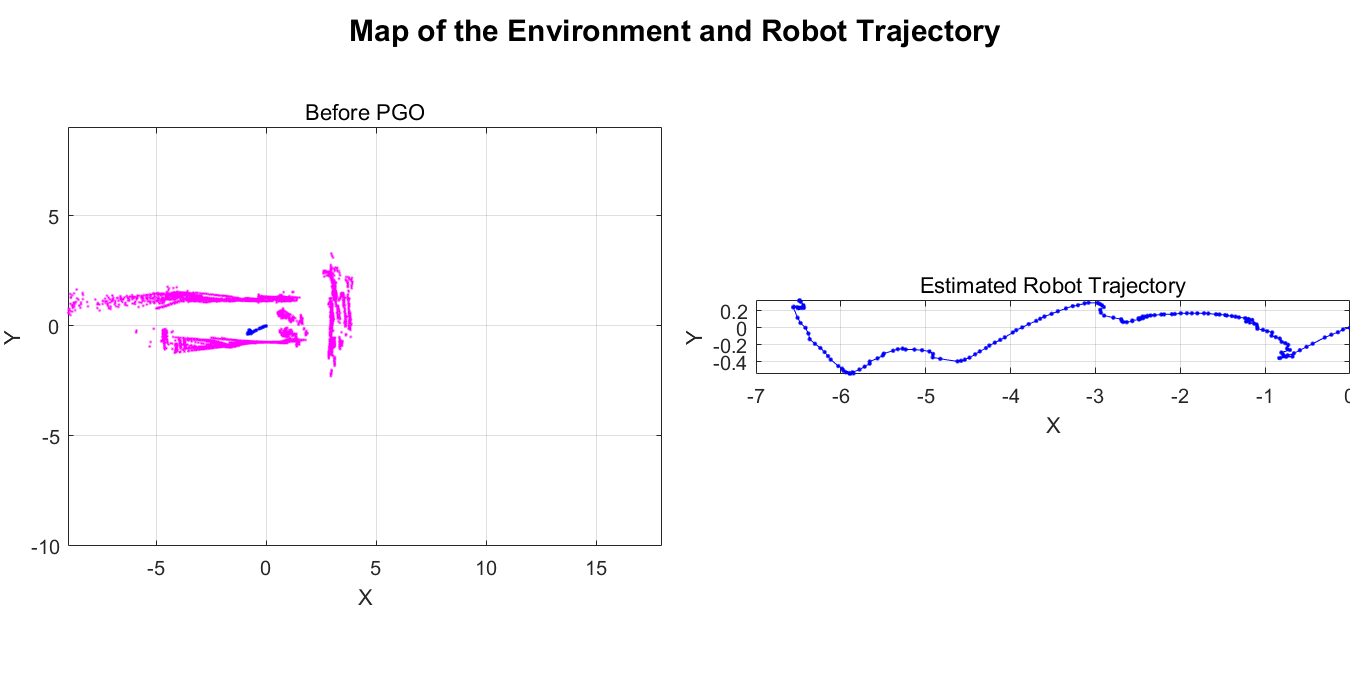

% Set maximum lidar range to be slightly smaller than maximum range of the
% scanner, as the laser readings are less accurate near maximum range 
% 최대인식거리8m
maxLidarRange = 10;
% Set the map resolution to 10 cells per meter, which gives a precision of
% 최소인식거리 10cm
mapResolution = 10;
% Create a pose graph object and define information matrix 
%포즈그래프와 정보 매트릭스 생성
pGraph = poseGraph;
infoMat = [1 0 0 1 0 1];
% Loop over each scan and estimate relative pose
%각 스캔을 반복하고 상대 포즈를 추정합니다
prevScan = scans1{1};
for i = 2:numel(scans1)
    currScan = scans1{i};
    % Estimate relative pose between current scan and previous scan
    %현재 스캔과 이전 스캔 간의 상대적 포즈 추정
    %matchScansGrid(currScan, refScan)는 그리드 기반 검색을 사용하여 참조 lidarScan과 현재 lidarScan 개체 사이의 상대적 포즈를 찾습니다.
    %lidar 스캔 쌍을 확률 그리드로 변환하고 그리드를 상호 연관시켜 두 스캔 사이의 포즈를 찾습니다. 이 함수는 분기 및 바인딩 전략을 사용하여 커다란 개별 검색 창에서 계산 속도를 높일 수 있습니다.matchScansGrid
    %[pose,stats]는 이전 입력 인수를 사용하여 검색 일치 결과에 대한 추가 통계를 반환합니다.
    [relPose,stats] = matchScansGrid(currScan,prevScan, ...
        'MaxRange',maxLidarRange,'Resolution',mapResolution);   
    % Refine the relative pose
    relPoseRefined = matchScans(currScan,prevScan,'initialPose',relPose);
    % Add relative pose to the pose graph object
    pGraph.addRelativePose(relPoseRefined,infoMat);
    ax = show(pGraph,'IDs','off');
    title(ax,'Estimated Robot Trajectory')
    drawnow
    prevScan = currScan;
end

Notice that the estimated robot trajectory drifts over time. The drift can be due to any of the following reasons:

- Noisy scans from the sensor without sufficient overlap

- Absence of significant features

- Inaccurate initial transformation, especially when rotation is significant

The drift in estimated trajectory results in an inaccurate map of the environment. Visualize the map and robot trajectory using the helperShow helper function, defined in the Supporting Functions section of this example.

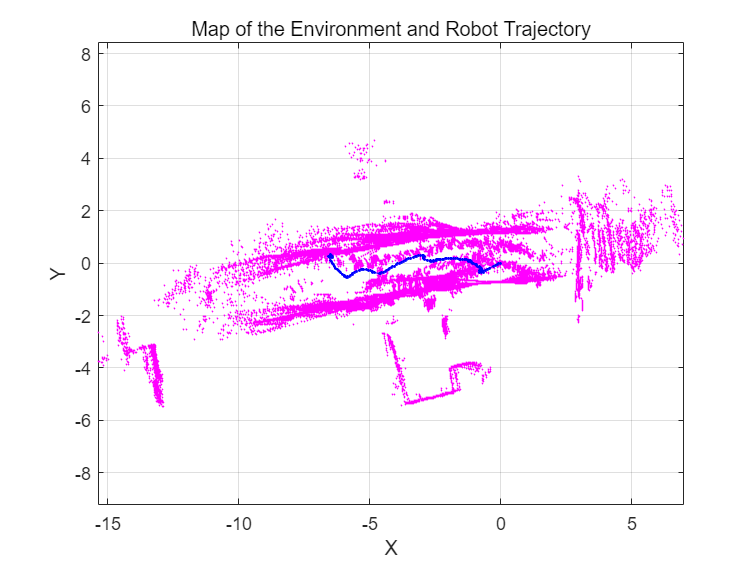

hFigMap = figure;
axMap = axes('Parent',hFigMap);
helperShow(scans1,pGraph,maxLidarRange,axMap);
title(axMap,'Map of the Environment and Robot Trajectory')

## Drift Correction

Correct the drift in trajectory by accurately detecting the *loops*, which are places the robot has previously visited. Add the loop closure edges to the pose graph, which helps to correct the drift in trajectory during pose graph optimization.

### Loop Closure Detection

*Loop closure detection* determines whether the robot has previously visited the current location. The search is performed by matching the current scan against the previous scans1 around the current robot location, within the radius specified by `loopClosureSearchRadius`. A scan is accepted as a match if the match score is greater than the specified `loopClosureThreshold`. Loop closures are detected using the `helperDetectLoop` helper function, which is attached to this example as a supporting file.

Adjust the loop closure parameters based on the quality of your results. You can increase the `loopClosureThreshold` value to reject false positives in loop closure detection, but the fuction might still return bad matches in environments with similar or repeated features. To address this, increase the `loopClosureSearchRadius` value to search a larger radius around the current pose estimate for loop closures, though this increases computation time. 

loopClosureThreshold = 110;
loopClosureSearchRadius = 2;
[loopClosureEdgeIds,loopClosurePoses] = helperDetectLoop(scans1,pGraph, ...
    loopClosureSearchRadius,loopClosureThreshold);

### Trajectory Optimization

Add the detected loop closure edges to the pose graph to correct the drift in the estimated trajectory. Use the [optimizePoseGraph](docid:nav_ref#mw_ead0d07b-dffc-4389-93ef-8fa1432c60cb) function to optimize the pose graph. 

% Add loop closure edges to pose graph
if ~isempty(loopClosureEdgeIds)
    for k = 1:size(loopClosureEdgeIds,1)
        pGraph.addRelativePose(loopClosurePoses(k,:),infoMat, ...
            loopClosureEdgeIds(k,1),loopClosureEdgeIds(k,2));
    end
end
% Optimize pose graph
updatedPGraph = optimizePoseGraph(pGraph);

## Visualization

Visualize the change in robot trajectory before and after pose graph optimization. The red lines represent loop closure edges.

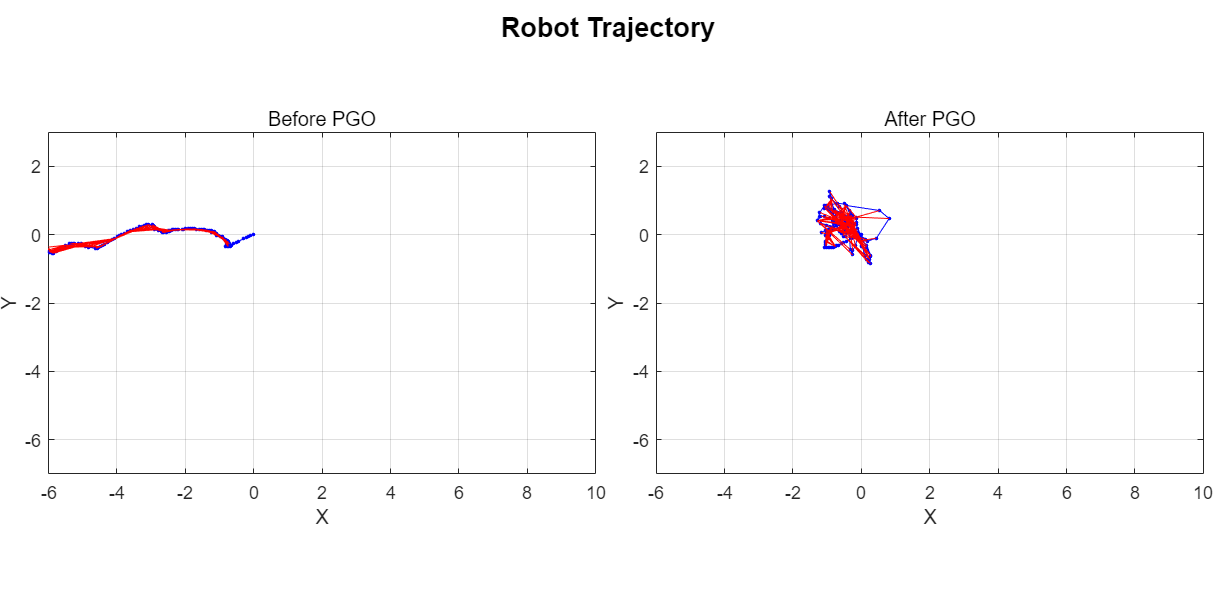

hFigTraj = figure('Position',[0 0 900 450]);

% Visualize robot trajectory before optimization
axPGraph = subplot(1,2,1,'Parent',hFigTraj);
axPGraph.Position = [0.04 0.1 0.45 0.8];
show(pGraph,'IDs','off','Parent',axPGraph);
title(axPGraph,'Before PGO')

% Visualize robot trajectory after optimization
axUpdatedPGraph = subplot(1,2,2,'Parent',hFigTraj);
axUpdatedPGraph.Position = [0.54 0.1 0.45 0.8];
show(updatedPGraph,'IDs','off','Parent',axUpdatedPGraph);
title(axUpdatedPGraph,'After PGO')
axis([axPGraph axUpdatedPGraph],[-6 10 -7 3])
sgtitle('Robot Trajectory','FontWeight','bold')

Visualize the map of the environment and robot trajectory before and after pose graph optimization.

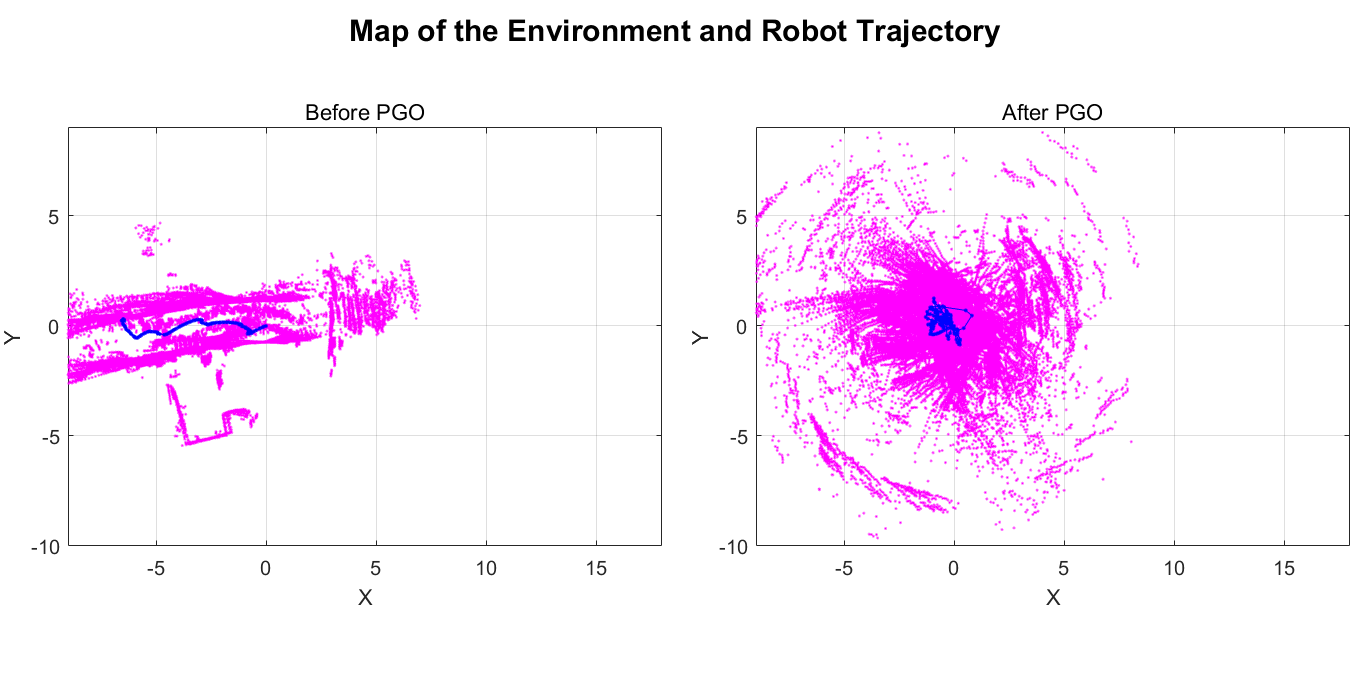

hFigMapTraj = figure('Position',[0 0 900 450]);

% Visualize map and robot trajectory before optimization
axOldMap = subplot(1,2,1,'Parent',hFigMapTraj);
axOldMap.Position = [0.05 0.1 0.44 0.8];
helperShow(scans1,pGraph,maxLidarRange,axOldMap)
title(axOldMap,'Before PGO')

% Visualize map and robot trajectory after optimization
axUpdatedMap = subplot(1,2,2,'Parent',hFigMapTraj);
axUpdatedMap.Position = [0.56 0.1 0.44 0.8];
helperShow(scans1,updatedPGraph,maxLidarRange,axUpdatedMap)
title(axUpdatedMap,'After PGO')
axis([axOldMap axUpdatedMap],[-9 18 -10 9])
sgtitle('Map of the Environment and Robot Trajectory','FontWeight','bold')

## Supporting Functions

 The `helperShow` helper function visualizes the map of the environment and trajectory of the robot. The function transforms lidar scans using their corresponding poses to create a map of the environment.

function helperShow(scans1,pGraph,maxRange,ax)
    hold(ax,'on')
    for i = 1:numel(scans1)
        sc = transformScan(scans1{i}.removeInvalidData('RangeLimits',[0.02 maxRange]), ...
            pGraph.nodes(i));
        scPoints = sc.Cartesian;
        plot(ax,scPoints(:,1),scPoints(:,2),'.','MarkerSize',3,'color','m')
    end
    nds = pGraph.nodes;
    plot(ax,nds(:,1),nds(:,2),'.-','MarkerSize',5,'color','b')
    hold(ax,'off')
    axis(ax,'equal')
    box(ax,'on')
    grid(ax,'on')
    xlabel('X')
    ylabel('Y')
end

## See Also

### Functions

[matchScansGrid](docid:lidar_ref#mw_0dd27c1c-985e-445c-8190-e7bde09cc7b3) | [matchScans](docid:lidar_ref#bvlvwfu-1) | [addRelativePose](docid:nav_ref#mw_32cae891-7154-4361-9e77-405c8153f0a1) | [show](docid:nav_ref#mw_9a52d6a0-a24b-4790-bc80-f2a071148bc3) | [optimizePoseGraph](docid:nav_ref#mw_ead0d07b-dffc-4389-93ef-8fa1432c60cb)

### Objects

[lidarScan](docid:lidar_ref#mw_dac2a159-8700-4349-9f00-15d193cbb3d2) | [poseGraph](docid:nav_ref#mw_25536ff1-7852-4b5c-9674-30fb0da71049)

*Copyright 2020 The MathWorks, Inc.*